# Example 2-1

# 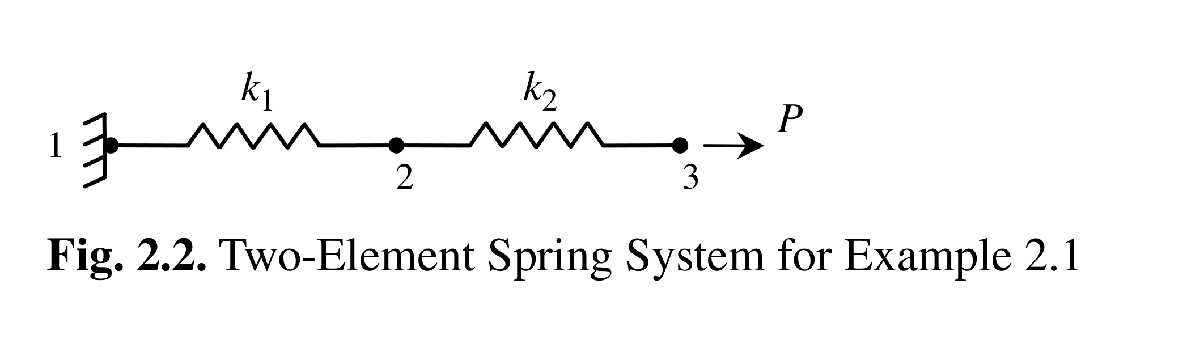

## Step 1: Descretizing the domain

ElemConnec = [1, 2; 2, 3]

ElemConnec =      1     2
     2     3


## Step 2: Writing the Element Striffness Matrices

k1 = SpringElementStiffness(100)

k1 =    100  -100
  -100   100


k2 = SpringElementStiffness(200)

k2 =    200  -200
  -200   200


## Step 3: Assembling the Global Stiffness Matrix

K = zeros(3, 3)

K =      0     0     0
     0     0     0
     0     0     0


K = SpringAssemble(K,k1,1,2)

K =    100  -100     0
  -100   100     0
     0     0     0


K = SpringAssemble(K,k2,2,3)

K =    100  -100     0
  -100   300  -200
     0  -200   200


## Step 4: Applying the Boundary Conditions

% U1 = 0; F2 = 0; F3 = 15kN;

## Step 5: Solving the Equations

k = K(2:3, 2:3)

k =    300  -200
  -200   200


f = [0; 15]

f =      0
    15


u = k\f

u =     0.1500
    0.2250


## Step 6: Post Processing

U = [0; u]

U =          0
    0.1500
    0.2250


F = K*U

F =   -15.0000
         0
   15.0000


u1 = [0; U(2)]

u1 =          0
    0.1500


f1 = SpringElementForces(k1, u1)

f1 =   -15.0000
   15.0000


u2 = [U(2); U(3)]

u2 =     0.1500
    0.2250


f2 = SpringElementForces(k2, u2)

f2 =    -15
    15
